********************
* SensorDataReader started on 192.168.31.5:3400
********************
Connection accepted from 192.168.31.116:47866


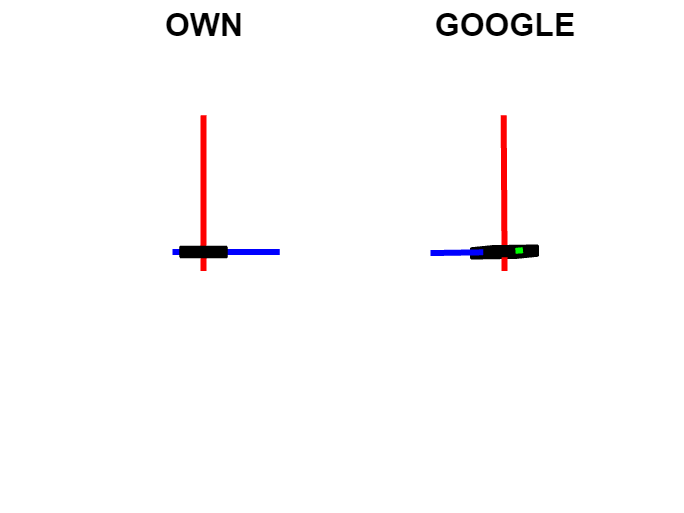

[xhat, meas] = filterTemplate();

# Task2

%filter and away from disturbance

[mu_acc, Sigma_acc] = approxGaussianTransform(meas.acc(:, ~any(isnan(meas.acc), 1)))

mu_acc =    -0.0698
    0.1296
    9.8607


Sigma_acc = 1.0e-03 *

    0.0538    0.0005   -0.0144
    0.0005    0.0416    0.0044
   -0.0144    0.0044    0.3620


[mu_gyr, Sigma_gyr] = approxGaussianTransform(meas.gyr(:, ~any(isnan(meas.gyr), 1)))

mu_gyr = 1.0e-03 *

   -0.0594
   -0.1348
    0.0545


Sigma_gyr = 1.0e-05 *

    0.0526    0.0675   -0.0118
    0.0675    0.2002   -0.0277
   -0.0118   -0.0277    0.0308


[mu_mag, Sigma_mag] = approxGaussianTransform(meas.mag(:, ~any(isnan(meas.mag), 1)))

mu_mag =    -8.9078
  -34.8681
   -6.2037


Sigma_mag =     0.0812   -0.0051    0.0049
   -0.0051    0.1222   -0.0141
    0.0049   -0.0141    0.0962


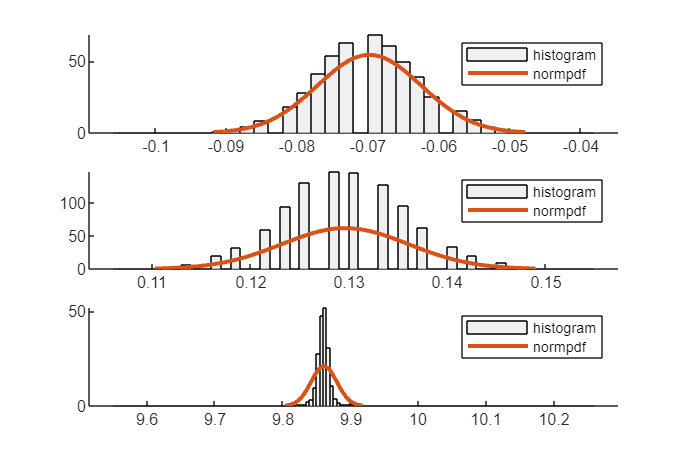

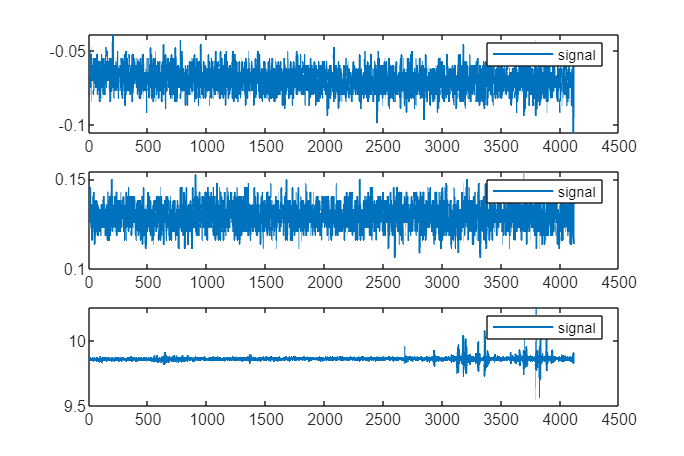

t1=meas.acc(:, ~any(isnan(meas.acc),1));
t2=meas.gyr(:, ~any(isnan(meas.gyr),1));
t3=meas.mag(:, ~any(isnan(meas.mag),1));
plothistogram(t1,mu_acc,Sigma_acc,t1);

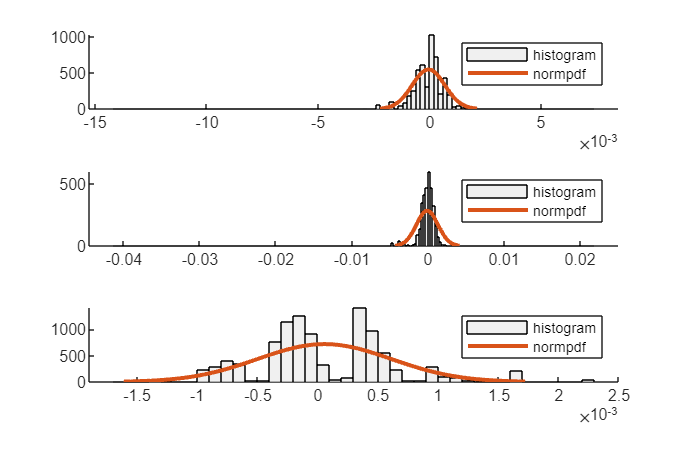

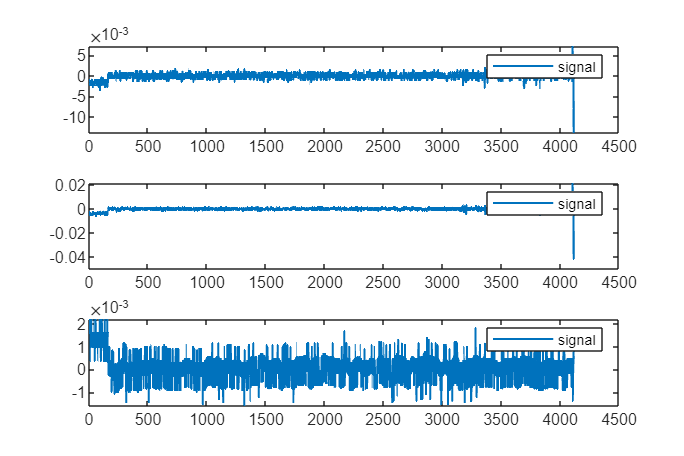

plothistogram(t2,mu_gyr,Sigma_gyr,t2);

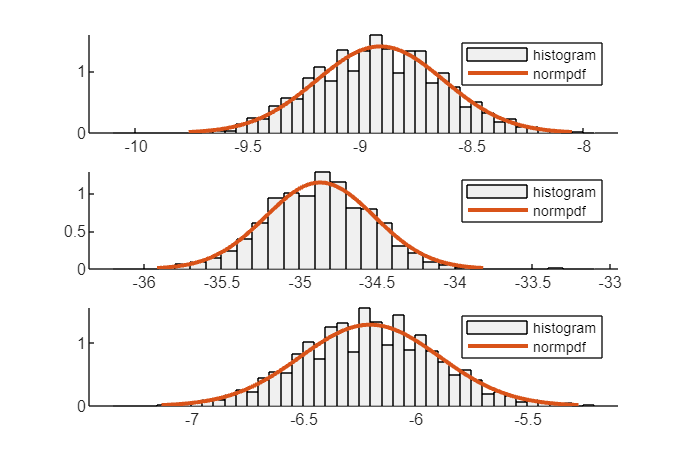

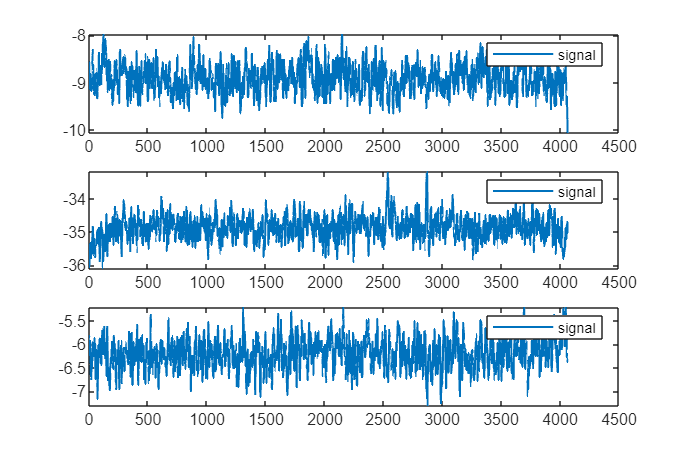

plothistogram(t3,mu_mag,Sigma_mag,t3);

# Task 3

%see note

# Task 4

# task 5

********************
* SensorDataReader started on 192.168.31.5:3400
********************
Connection accepted from 192.168.31.116:49774


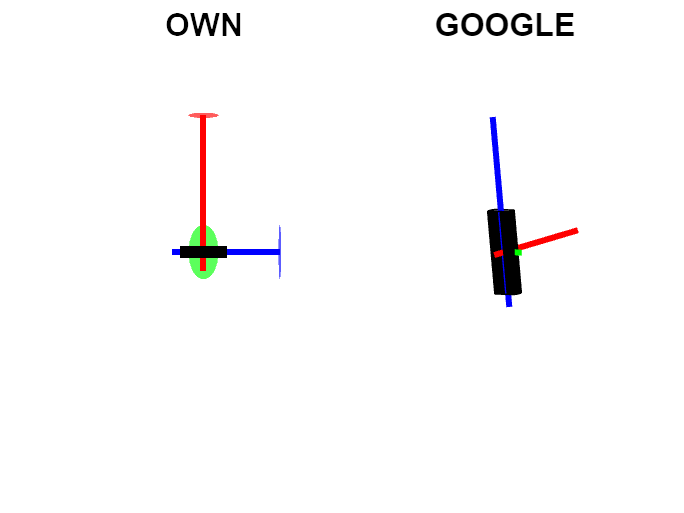

Unsuccessful connecting to client!
Make sure to start streaming from the phone *after*running this function!

[xhat1, meas1] = filterTemplate_new();

[mu_acc1, Sigma_acc1] = approxGaussianTransform(meas1.acc(:, ~any(isnan(meas1.acc), 1)))

mu_acc1 =     9.5147
   -0.1602
   -0.0316


Sigma_acc1 =     0.5338    0.1012   -0.5397
    0.1012    0.2963   -0.2908
   -0.5397   -0.2908    4.7205


[mu_gyr1, Sigma_gyr1] = approxGaussianTransform(meas1.gyr(:, ~any(isnan(meas1.gyr), 1)))

mu_gyr1 =     0.0000
    0.0017
    0.0070


Sigma_gyr1 =     0.7957   -0.0157    0.0295
   -0.0157    0.5608   -0.0121
    0.0295   -0.0121    0.0433


[mu_mag1, Sigma_mag1] = approxGaussianTransform(meas1.mag(:, ~any(isnan(meas1.mag), 1)))

mu_mag1 =   -28.6830
   -9.7440
   10.3838


Sigma_mag1 =    10.9009    2.8516    6.9303
    2.8516   10.8640   10.3514
    6.9303   10.3514   65.0233


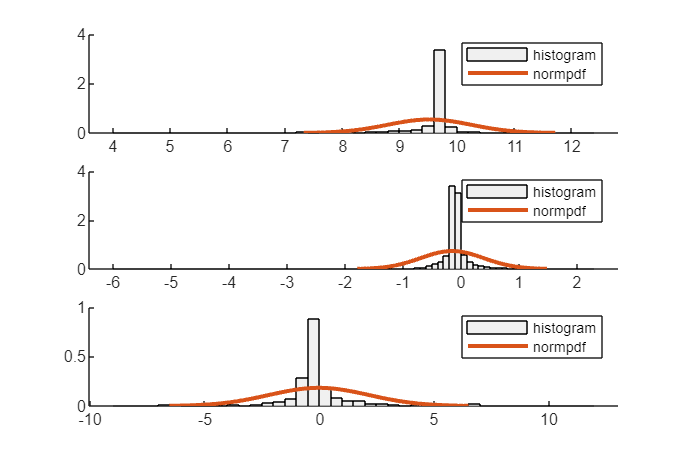

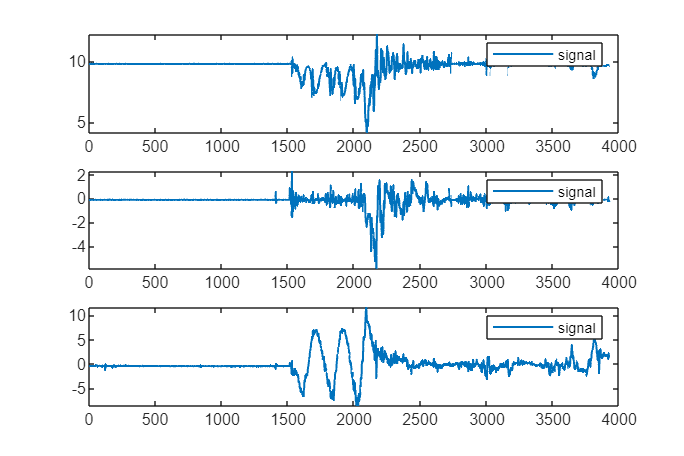

t1=meas1.acc(:, ~any(isnan(meas1.acc),1));
t2=meas1.gyr(:, ~any(isnan(meas1.gyr),1));
t3=meas1.mag(:, ~any(isnan(meas1.mag),1));
plothistogram(t1,mu_acc1,Sigma_acc1,t1);

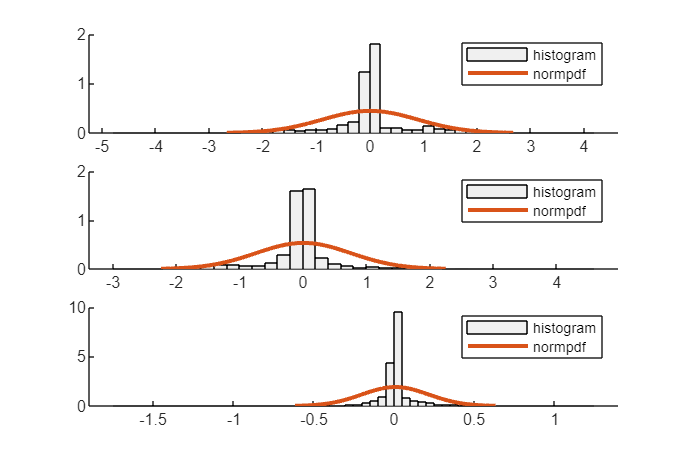

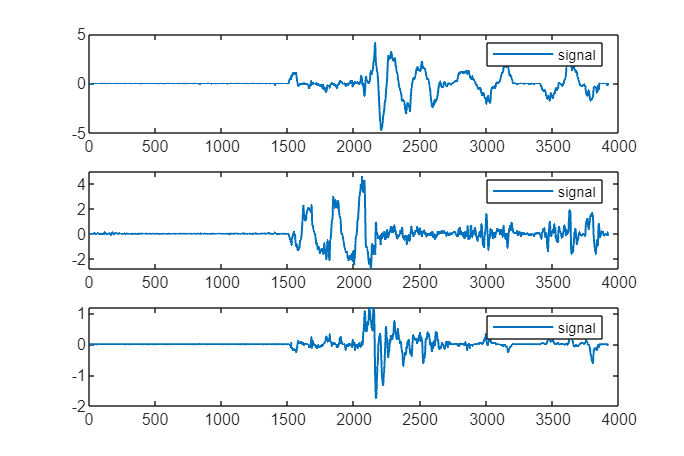

plothistogram(t2,mu_gyr1,Sigma_gyr1,t2);

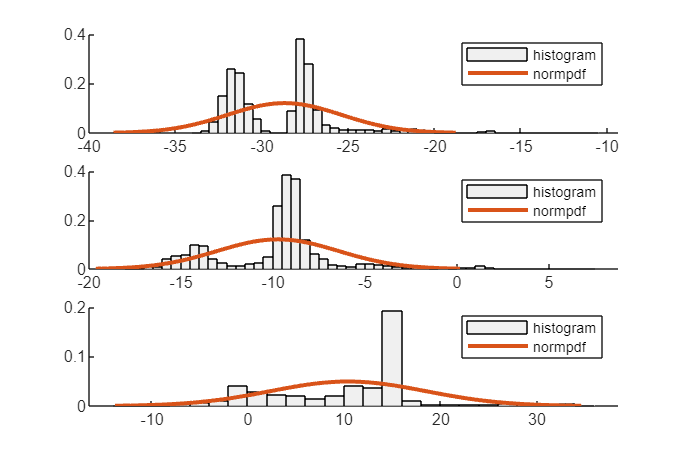

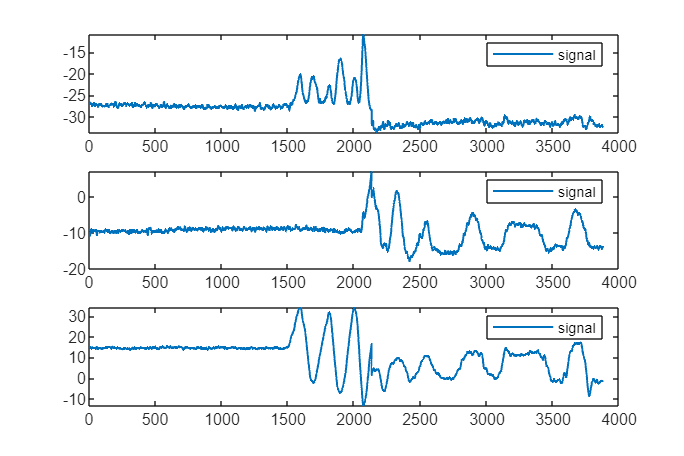

plothistogram(t3,mu_mag1,Sigma_mag1,t3);